## Problem 1

In our first example we are looking at the temperature reading (meta-data) associated with an experiment. For the experiment to work reliably, the temperature should be at around 12 Kelvin, and if we look at the data it is mostly consistent with 12 Kelvin to within the 0.4 degree precision of the thermometry and the thermal control system (standard deviation). However, there are times when the thermal control system misbehaved and the temperature was not near 12 K, and in addition there are various glitches in the thermometry that give anomalously high and low readings (the reading does not match the real temperature). We definitely want to identify and throw out all the data when the thermal control system was not working (and the temperature was truly off from nominal). While it is possible to have an error in the thermometry such that the true temperature was fine, and we just had a wonky reading, in an abundance of caution we want to throw those values out too.

To make this a bit concrete, we will simulate a little data. Start by simulating 100k 'good' data points assuming Gaussian fluctations, and because we are playing god adding the following 'bad' datapoints: {10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7}

A) So our goal is to identify bad data and throw it out.

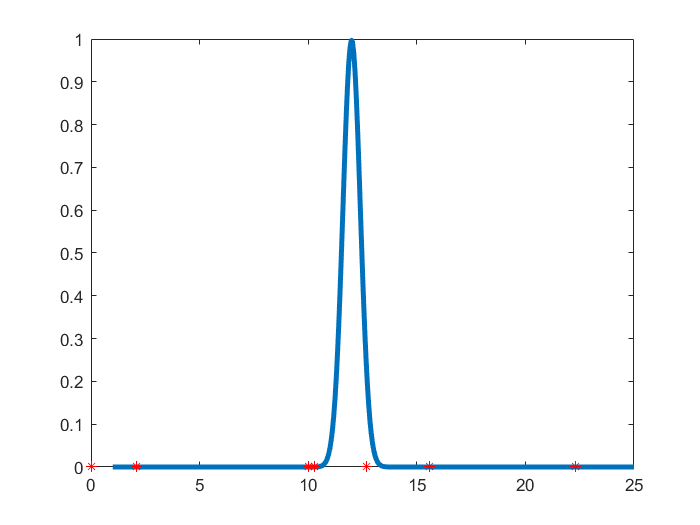

clc; close all; clear all;
x = 1:100000;
temp = 1:(25/length(x)):25;
goodData = makedist("Normal",'mu',12,'sigma',.4);
badData = [10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7];
data = pdf(goodData,temp);
plot(temp,pdf(goodData,temp),"LineWidth",3);
hold on
plot(badData,0,'r*');
hold off

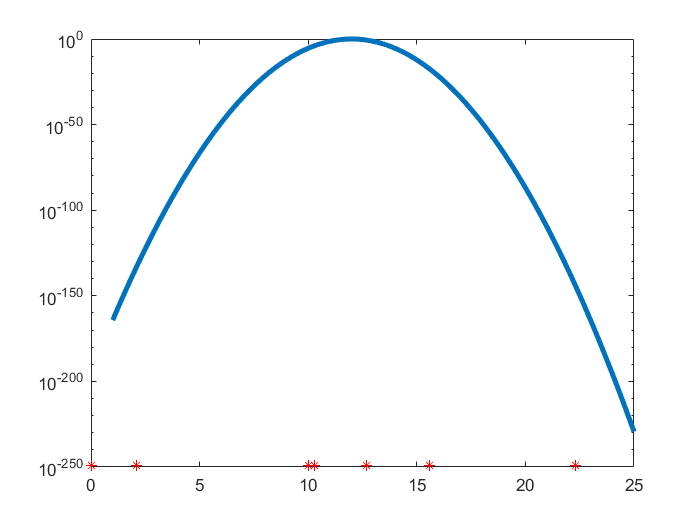

plot(temp,pdf(goodData,temp),"LineWidth",3);
hold on
plot(badData,1*10^-249,'r*');
set(gca,'YScale','log')
hold off

% for i = badData
%     %index = find(temp == i);
%     for j=1:length(temp)
%         if(abs(i-temp(j)) < 1e4*eps(min(abs(i),abs(temp(j)))))
%             index = j;
%         end
%     end
%     newData(index) = newData(index)+(1/100000);
% end
% newData = newData/norm(data);
% plot(temp,newData,"LineWidth",3);
% plot(temp,newData,"LineWidth",3);
% set(gca,'YScale','log')

Finding magnitude of sigma's for each bad data point

for i = 1:length(badData)
    probability(i) = cdf(goodData, badData(i));
    sigma(i) = norminv(probability(i));
end
badData

badData =    10.0000   10.3000    2.1000         0         0   15.6000   22.3000   12.7000


probability

probability =     0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    1.0000    0.9599


sigma

sigma =    -5.0000   -4.2500  -24.7500  -30.0000  -30.0000       Inf       Inf    1.7500


    4 sigma looks like a good criteria for finding bad data given that only one of the bad data values we have is 4 sigma or less.

2) What is the probability of our data producing a point that looks like bad data?

3) cdf(sigma = -cutoff sigma) + (1-cdf(sigma = +cutoff sigma)

4) If we take out anything that's more than 4 sigma away from the mean, there will be 4 possibilities for each piece of data

    a) Within the 4 sigma bounds, we correctly identified legitimate data

    b) Within the 4 sigma bounds we incorrectly identified data we thought was legitimate

    c) Outside the 4 sigma range, we correctly threw out bad data.

    d) Outside the 4 sigma range we threw out good data because it didn't meet as high a standard.

X = ['Sigma = ',num2str(4)];
disp(X)

Sigma = 4


a = round(SigmaCdf(goodData,4)*100000)

a = 99994


b = NumberWithinRange(goodData,badData,4)

b = 1


c = length(badData)-b

c = 7


d = 100000-a

d = 6

1b) The number of ommisions depends highly upon our statistical threshold. The number of times we threw out good data is very predictable by simply repeating the above calculations for various sigma as done below.

1c) The less stringent our statistical method is, the more bad data gets in, as shown below.

for i=1:10
    X = ['Sigma = ',num2str(i)];
    disp(X)
    a = round(SigmaCdf(goodData,i)*100000)

    b = NumberWithinRange(goodData,badData,i)

    c = length(badData)-b

    d = 100000-a
end

Sigma = 1


a = 68269

b = 0

c = 8

d = 31731

Sigma = 2


a = 95450

b = 1

c = 7

d = 4550

Sigma = 3


a = 99730

b = 1

c = 7

d = 270

Sigma = 4


a = 99994

b = 1

c = 7

d = 6

Sigma = 5


a = 100000

b = 3

c = 5

d = 0

Sigma = 6


a = 100000

b = 3

c = 5

d = 0

Sigma = 7


a = 100000

b = 3

c = 5

d = 0

Sigma = 8


a = 100000

b = 3

c = 5

d = 0

Sigma = 9


a = 100000

b = 3

c = 5

d = 0

Sigma = 10


a = 100000

b = 3

c = 5

d = 0

## Problem 2

In this example we will be looking for asteroids. If we look at the alignment of stars on subsequent images, they don't perfectly align due to atmospheric and instrumental effects (even ignoring proper motion). The resulting distribution is two dimensional, and for this lab let's assume it is a 2D Gaussian with 1 arcsecond RMS. Or said another way, if I histogram how far all the (stationary) stars appear to have moved I get something like:

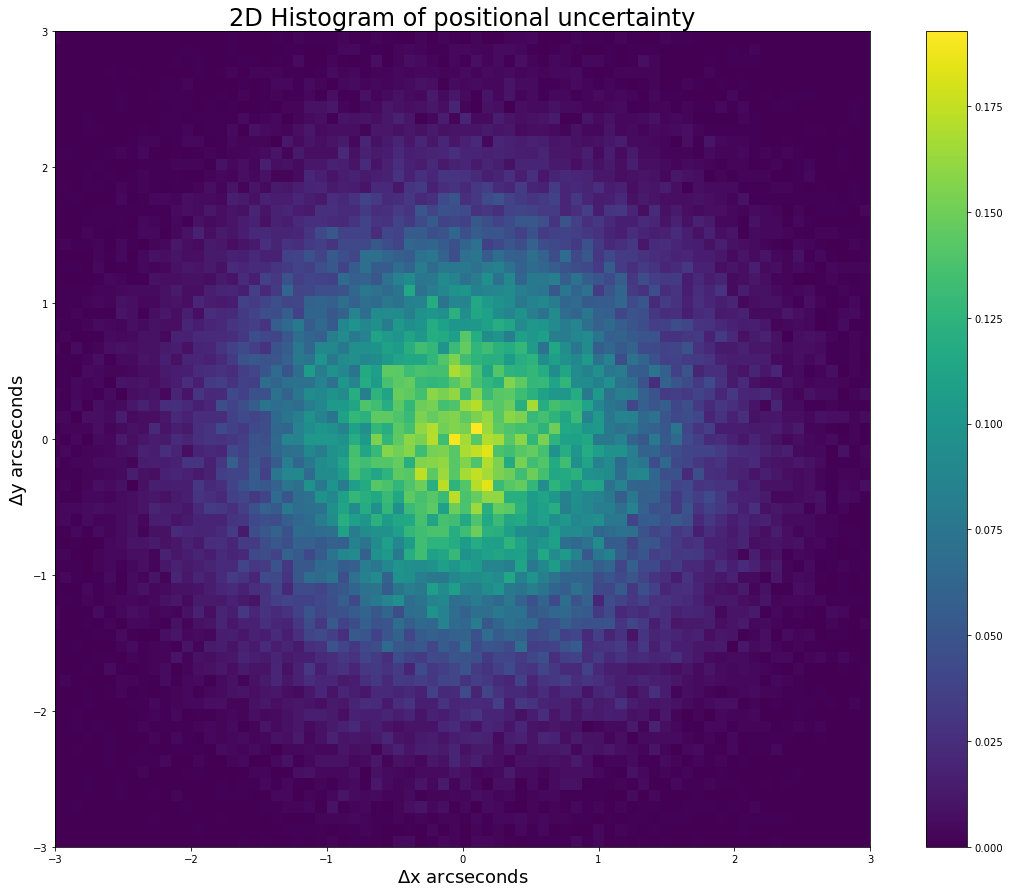

If I have a potential asteroid, it will have some true movement between the images. We would like a '5 sigma' detection of movement. What is that distance in arcseconds?

1) How likely is it that the signal is outside the acceptable range of 5 sigma.

2) probability = cdf(sigma = - 5)+(1-cdf(sigma = + 5)

## Problem 3

As we discussed in class, one of the key backgrounds for gamma-ray telescopes are cosmic rays. Cosmic rays are charged particles—usually protons or electrons but can include atomic nuclei such a alpha particles (helium) or iron. Because of their charge cosmic rays spiral in the magnetic field of the galaxy. From the perspective of the Earth they appear to be coming uniformly from all directions like a high energy gas, and the direction the cosmic ray is travelling when it reaches the Earth tells us nothing about where it came from because we don't know what tortured path it has taken through the galaxy to reach us. However, at trillion electron volt energies and above, the spiral loops are fairly big and the sun and the moon will block cosmic rays. This means the sun and the moon appear as holes in the cosmic ray sky (cosmic rays from that direction are absorbed).

Assume a moon sized patch on the sky we normally have a cosmic ray rate of 1 cosmic ray per minute (arrivals are random in time). If we can observe where the moon is for 8 hours per night (not too close to the horizon) and we observe for 15 days and see 6800 cosmic rays, what is the signficance of our moon shadow detection?

1) What's the probability that our detection of 6800 cosmic rays over the 15 day period was caused by random chance?

2) 

expectedNumber = 1*60*8*15 %based on what is typically observed in a moon sized patch of sky.

expectedNumber = 7200

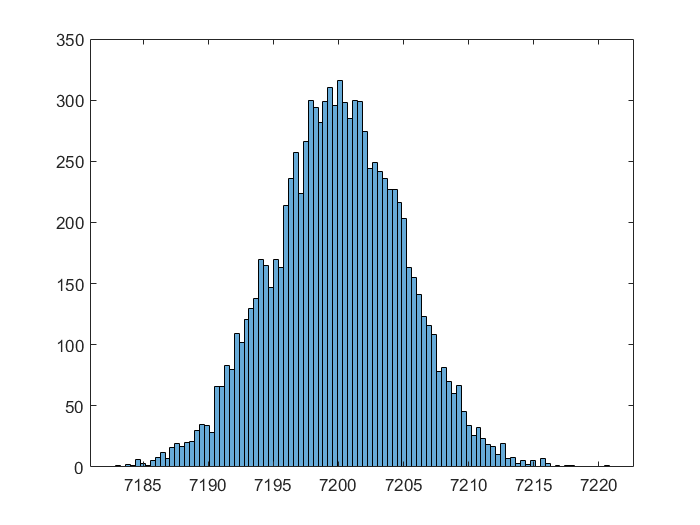

sigma = 5;
days15 = normrnd(expectedNumber,sigma,100);
histogram(days15,100)

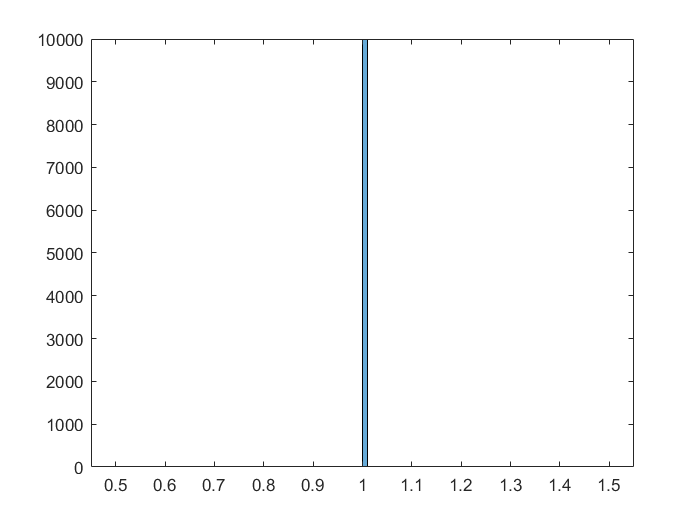


integ = cdf('normal',days15);
histogram(integ,100)

function a = SigmaCdf(pd,x)         
    mu = mean(pd);                     
    sigma = x*std(pd);                 
    a = cdf(pd,mu+sigma)-cdf(pd,mu-sigma);
end

function b = NumberWithinRange(pd,x,sigma2)
    b = 0;
    for i = 1:length(x)
        probability(i) = cdf(pd, x(i));
        sigma(i) = -norminv(probability(i));
        if abs(sigma(i)) <= sigma2
            b=b+1;
        end
    end
end